# AGC(自動発電制御)

#  controller.broadcast_PI_AGC

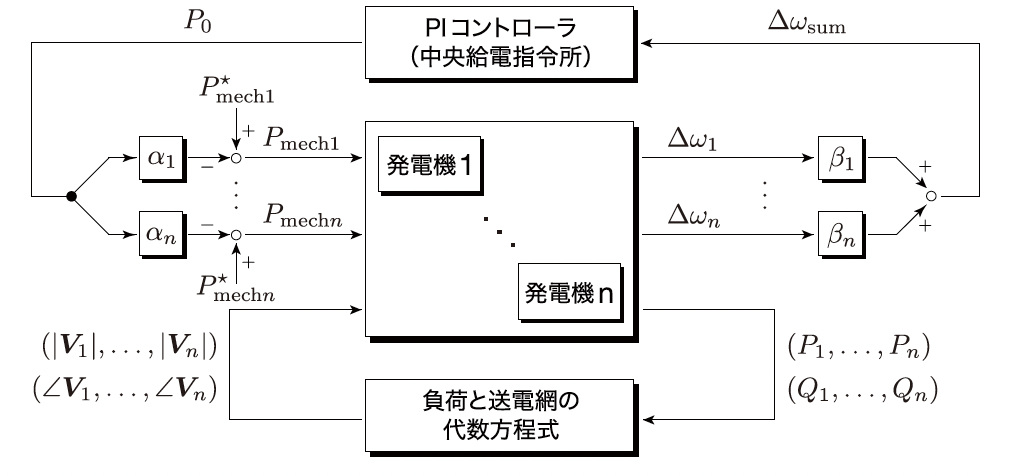

引用元：電力系統のシステム制御工学 

**分類：global controller**

**プロパティ**

- 入力ポート(port_input)     ：`Pmech`

- 観測ポート(port_observe)：`omega`

- 入力機器番号(index_input)     ：ユーザ指定

- 観測機器番号(index_observe)：ユーザ指定

- PIゲイン(Kp,Ki) ：ユーザ指定(ネガティブフィードバックにするには負の値を設定)

- 観測側の寄与係数の設定値(default_K_observe)：ユーザ指定(index_observeと同じサイズ)

- 入力側の寄与係数の設定値(default_K_input)     ：ユーザ指定(index_inputと同じサイズ)

- 観測側の寄与係数(K_observe)：default_K_observeから並列してる機器に対応する寄与係数のみを取得し正規化した配列

- 入力側の寄与係数(K_input)     ：default_K_inputから並列してる機器に対応する寄与係数のみを取得し正規化した配列

**数理モデル**

         
$$\Delta \;\omega \;=\left\lbrack \begin{array}{cccc}
K_{\textrm{obser} \textrm{ve}\;i}  & K_{\textrm{observe}\;\;j}  & \cdots  & K_{\textrm{observe}\;k} 
\end{array}\right\rbrack \;\;\left\lbrack \begin{array}{c}
\omega {\;}_i \\
\omega {\;}_j \\
\vdots \\
\omega {\;}_k 
\end{array}\right\rbrack$$


            
$$\Downarrow$$


    
$$\left\lbrace \begin{array}{ll}
\dot{\;\xi \;} =\Delta \;\omega \; & \\
y=K_P \;\Delta \omega +K_{I\;} \xi \; & 
\end{array}\right.$$


            
$$\Downarrow$$


        $\left\lbrack \begin{array}{c}
P_{\textrm{mech}} {\;}_i \\
P_{\textrm{mech}} {\;}_j \\
\vdots \\
P_{\textrm{mech}} {\;}_k 
\end{array}\right\rbrack$ = $\left\lbrack \begin{array}{c}
K_{\textrm{input}} {\;}_i \\
K_{\textrm{input}} {\;}_j \\
\vdots \\
K_{\textrm{input}} {\;}_k 
\end{array}\right\rbrack$ y

 
% 接続するネットワークを定義
net = network.IEEE9bus_past;

% AGCのパラメータをセット
    index_input   = [1,2,3]; %機器1,2,3の入力ポート"Pmech"に入力
    index_observe = [1,2,3]; %機器1,2,3の状態"omega"を観測
    Kp = -10; % Pゲイン
    Ki = -100; % Iゲイン

con = controller.broadcast_PI_AGC(net,index_input,index_observe,Kp,Ki);
net.add_controller(con);
u = struct('time',[1,2,30],'index',5,'u',[1;1]*[0,0.1,0.1],'method','foh','function',[]);
out = net.simulate([0,30], 'input',u);
out.plot;
set(gcf,'Position',[0,0,1000,600])